Ki = 3.33;
Kp = 5.66;
Kd = 4.14;

F = tf(1, [1, 1])

F =
 
    1
  -----
  s + 1
 
Continuous-time transfer function.



G = tf(3, [1, 4, 5, 0])

G =
 
          3
  -----------------
  s^3 + 4 s^2 + 5 s
 
Continuous-time transfer function.



Gc = tf([Kd, Kp, Ki], [1, 0])

Gc =
 
  4.14 s^2 + 5.66 s + 3.33
  ------------------------
             s
 
Continuous-time transfer function.




T = F * feedback(G * Gc, 1)

T =
 
              12.42 s^2 + 16.98 s + 9.99
  ---------------------------------------------------
  s^5 + 5 s^4 + 21.42 s^3 + 34.4 s^2 + 26.97 s + 9.99
 
Continuous-time transfer function.



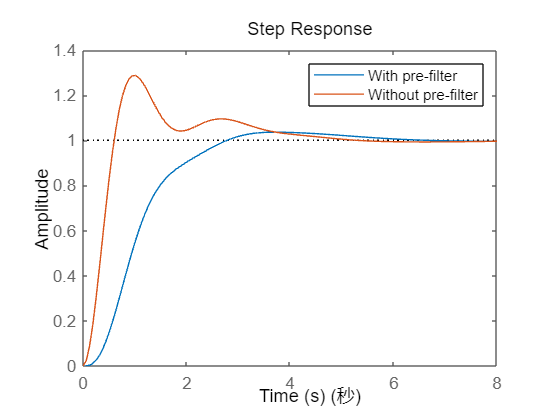


step(T, feedback(G * Gc, 1))
legend(["With pre-filter", "Without pre-filter"])
title("Step Response")
xlabel("Time (s)")
ylabel("Amplitude")